#                        Blind Source Separation

##                                            HW6-Section-2

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/02/20   

clear; clc; close all;

## Part-1:

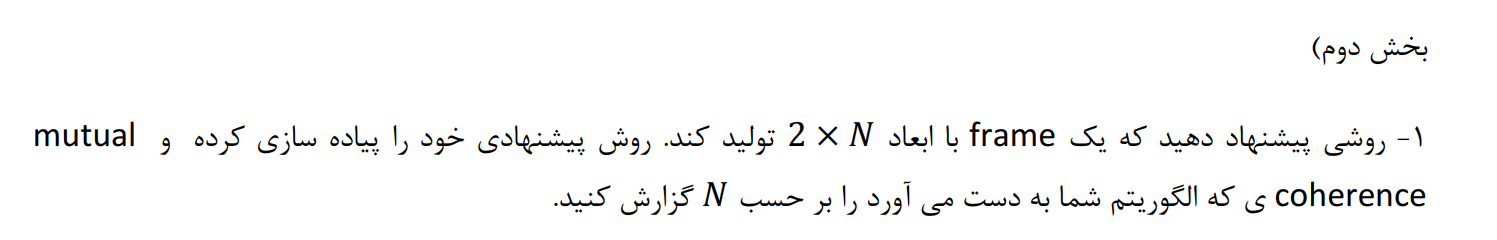

% Example try on given Dictionary Matrix of Section-1:
Data_Q1 = load("hw6-part1.mat");
D = Data_Q1.D;
[MU_out, MU_Index_Out] = MU_Calc_Mine(D);
disp("Columns "+MU_Index_Out(1)+" and "+MU_Index_Out(2)+" are most coherent!")

Columns 2 and 10 are most coherent!


disp("Mu is equal to : "+MU_out);

Mu is equal to : 0.8839


2*N Frame:

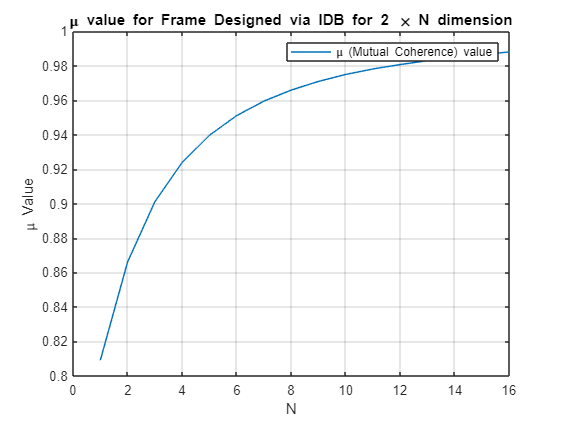

% Design incoherent frames using a distance barrier.
% Bisection is used to find the best coherence value.


m = 2;
N = 5:20;         % frame size
K = 2000;        % number of iterations

%-------------------------------------------
% IDB parameters
lambda = 0.2;    % trade-off factor
gamma0 = 0.1;    % initial step size
rho = 0.999;     % step size decrease factor
search_it = 5;   % number of halving steps in gradient search
tol_stop = 1e-4; % stopping tolerance
K_bis = 15;      % number of bisection iterations
%-------------------------------------------
Sol_IDB = cell(1,length(N));
MU_calc_Vec = zeros(1,length(N));

for i=1:length(N)
n = N(i);

mu_min = getBound(m,n); % lower coherence bound
Fr = normc(randn(m,n));
mu_max = max(max(abs(Fr'*Fr - eye(n)))); % coherence of a random frame

[F_IDB, coh_best, iter_total_count] = bisection_idb(mu_min, mu_max, K_bis, m, n, K, lambda,...
                                      gamma0, rho, search_it, tol_stop);
Sol_IDB{1,i} = F_IDB;
MU_calc_Vec(i) = MU_Calc_Mine(F_IDB) ;

end



figure()
plot(MU_calc_Vec)
grid on
xlabel("N")
ylabel("\mu Value")
title("\mu value for Frame Designed via IDB for 2 \times N dimension");
legend("\mu (Mutual Coherence) value")

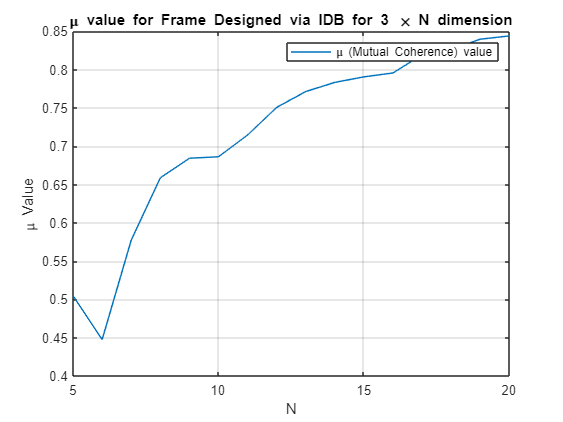


m = 3;
N = 5:20;         % frame size
K = 2000;        % number of iterations

%-------------------------------------------
% IDB parameters
lambda = 0.2;    % trade-off factor
gamma0 = 0.1;    % initial step size
rho = 0.999;     % step size decrease factor
search_it = 5;   % number of halving steps in gradient search
tol_stop = 1e-4; % stopping tolerance
K_bis = 15;      % number of bisection iterations
%-------------------------------------------
Sol_IDB = cell(1,length(N));
MU_calc_Vec = zeros(1,length(N));

for i=1:length(N)
n = N(i);

mu_min = getBound(m,n); % lower coherence bound
Fr = normc(randn(m,n));
mu_max = max(max(abs(Fr'*Fr - eye(n)))); % coherence of a random frame

[F_IDB, coh_best, iter_total_count] = bisection_idb(mu_min, mu_max, K_bis, m, n, K, lambda,...
                                      gamma0, rho, search_it, tol_stop);
Sol_IDB{1,i} = F_IDB;
MU_calc_Vec(i) = MU_Calc_Mine(F_IDB) ;

end



figure()
plot(N , MU_calc_Vec)
grid on
xlabel("N")
ylabel("\mu Value")
title("\mu value for Frame Designed via IDB for 3 \times N dimension");
legend("\mu (Mutual Coherence) value")

function [MU_out, MU_Index_Out] = MU_Calc_Mine(D)

Temp     = (ones(size(D'*D)) - eye(size(D'*D))).* abs( D'*D );
[MU_Vals , MU_Index] =  max(Temp)  ;
[MU_out , MU_Index2]  = max(MU_Vals);

MU_Index_Out = [MU_Index2 , MU_Index(MU_Index2)];
end


